Lab 7

Event selection optimization You and your lab partner should pick *different* pT (transverse momentum) samples (one uses low-pT sampels and the other use high-pT samples) for this lab. In each pT sample, there are dedicated training samples for event selection optimization. All studies should be carried out by normalizing Higgs and QCD samples in each pT sample to given expected yields accordingly (See Dataset descriptions).

IM USING HIGH PT

h5disp("higgs_100000_pt_1000_1200.h5")

HDF5 higgs_100000_pt_1000_1200.h5 
Group '/' 
    Dataset 'higgs_100000_pt_1000_1200' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


h5disp("qcd_100000_pt_1000_1200.h5")

HDF5 qcd_100000_pt_1000_1200.h5 
Group '/' 
    Dataset 'qcd_100000_pt_1000_1200' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000



higgs = h5read("higgs_100000_pt_1000_1200.h5",'/higgs_100000_pt_1000_1200');
qcd = h5read("qcd_100000_pt_1000_1200.h5",'/qcd_100000_pt_1000_1200');

- Make a stacked histogram plot for the feature variable: mass (a regular histogram)

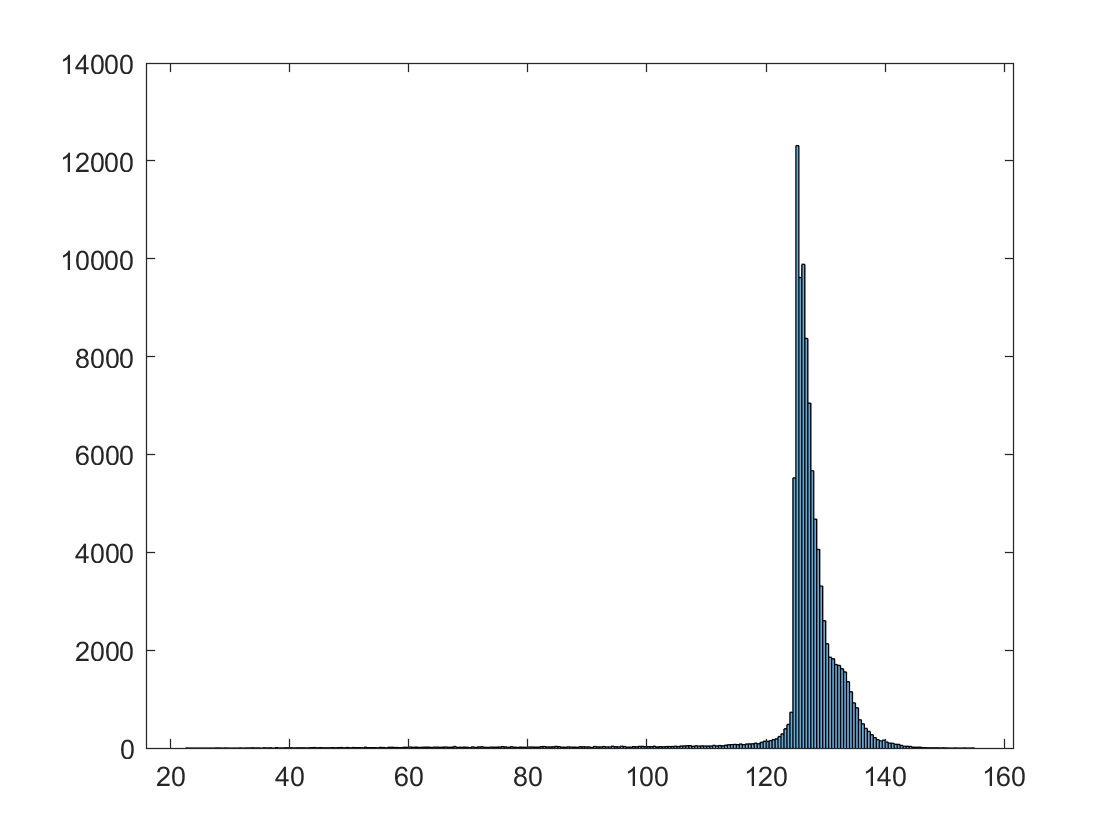

hh = histogram(higgs(4,:));

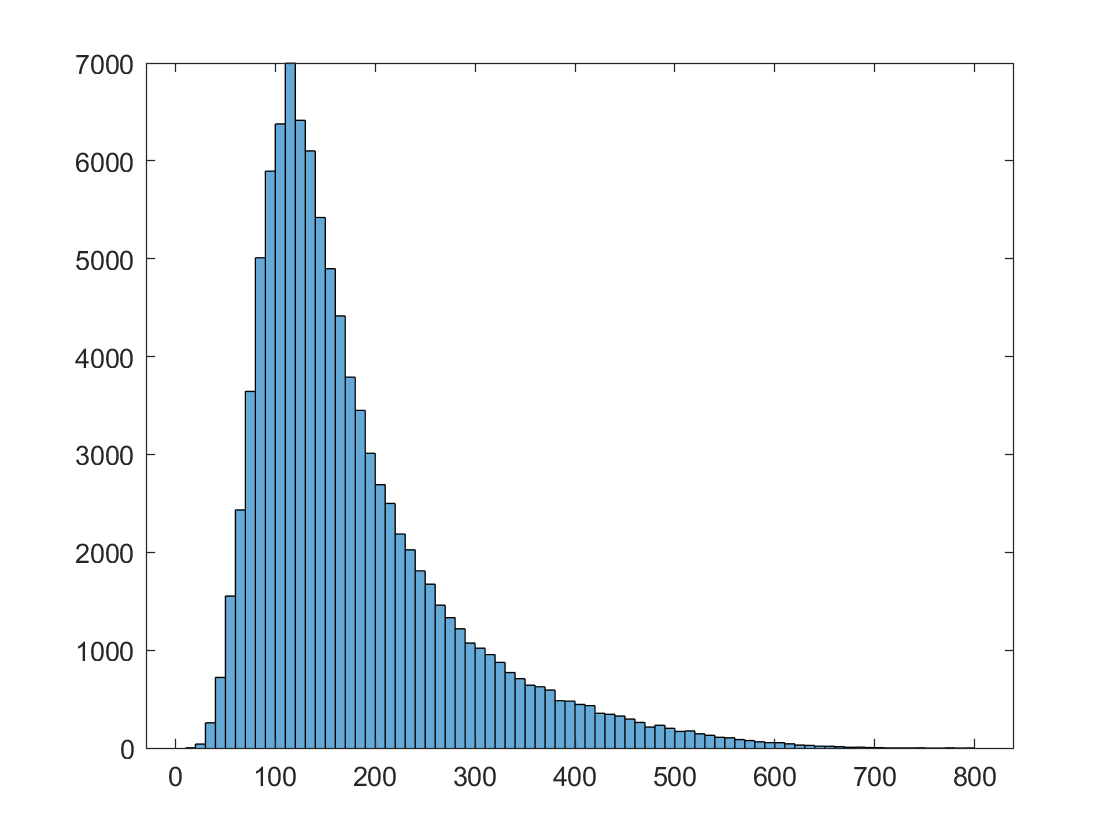

%%signal
hq = histogram(qcd(4,:));

%%background
Nhiggs = 50;
Nqcd = 2000;

- Evaluate expected significance without any event selection.

- Use Poisson statistics for significance calculation

poiss = makedist('Poisson','lambda',2000);
signal = 2050;

pr = cdf(poiss,signal)

pr = 0.8704

sigma = norminv(pr)

sigma = 1.1282

- Compare your number of NHiggs/(√NQCD)NHiggs/(NQCD). If they are equivalent, explain your findings.

- --Number of events is a poisson distribution with lambda Nhiggs or Nqcd--

- significance of 2050 in a poisson 2000 dist

ratio = Nhiggs/(sqrt(Nqcd))

ratio = 1.1180

-- sigma??? :)

- Identify mass cuts to optimize the expected significance.

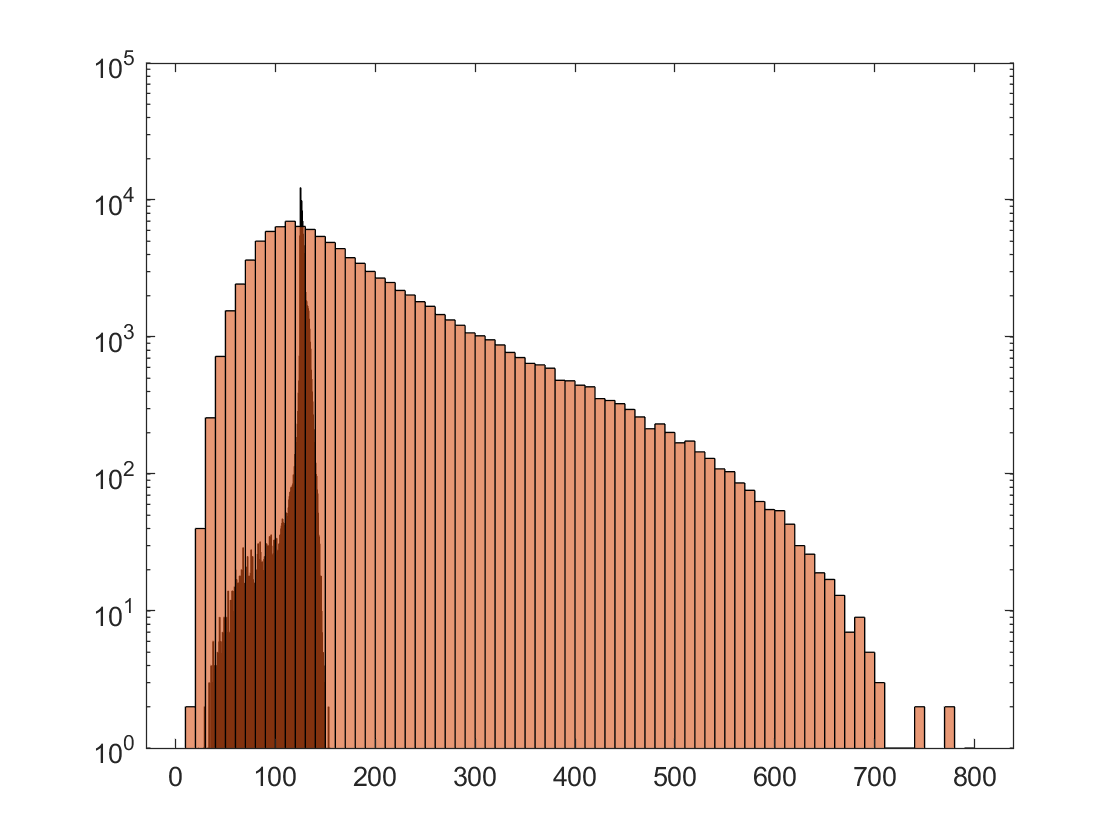

histogram(higgs(4,:));
hold on
histogram(qcd(4,:));
set(gca,'Yscale','log')
hold off

The Higgs data runs from ~(25 to 175) so we can cut out any background before and after that.

l = length(higgs(4,:));
hcount = zeros(1,l);

for i = 1:l
    if (100 < higgs(4,i)) && (higgs(4,i) < 140)
        hcount(i) = 1;
    else
        hcount(i) = 0;
    end
end

Nhiggs = sum(hcount)*50/l

Nhiggs = 48.6715


bcount = zeros(1,l);

for i = 1:l
    if (100 < qcd(4,i)) && (qcd(4,i) < 140)
        bcount(i) = 1;
    else
        bcount(i) = 0;
    end
end

Nqcd = sum(bcount)*2000/l

Nqcd = 517.8000


ratio = Nhiggs/(sqrt(Nqcd))

ratio = 2.1389

<FIND SIGNIFICANCE AND COMPARE>

-- for this, use the ratio!!!! Isolate stuff then find Nhiggs and Nqcd :)))))

j = 100:1:120;
k = 121:1:140;

sigs = zeros(length(j),length(k));

for n = 1:length(j)
    for m = 1:length(k)
        for i = 1:l
            if (j(n) < higgs(4,i)) && (higgs(4,i) < k(m))
                hcount(i) = 1;
            else
                hcount(i) = 0;
            end
        end
        for i = 1:l
            if (j(n) < qcd(4,i)) && (qcd(4,i) < k(m))
                bcount(i) = 1;
            else
                bcount(i) = 0;
            end
        end
        Nhiggs = sum(hcount)*50/l;
        Nqcd = sum(bcount)*2000/l;
        sigs(n,m) = Nhiggs/(sqrt(Nqcd));
    end
end

M = max(sigs,[],'all')

M = 3.3696

[A,B] = max(sigs,[],"all",'linear')

A = 3.3696

B = 231

sigs =     0.0720    0.0808    0.0939    0.1164    0.2855    0.8703    1.3391    1.6456    1.8410    1.9592    2.0288    2.0827    2.1313    2.1695    2.1877    2.1916    2.1854    2.1736    2.1575    2.1389
    0.0718    0.0809    0.0942    0.1170    0.2892    0.8840    1.3603    1.6711    1.8687    1.9877    2.0575    2.1112    2.1596    2.1975    2.2151    2.2183    2.2114    2.1988    2.1820    2.1625
    0.0718    0.0810    0.0946    0.1178    0.2934    0.8993    1.3838    1.6992    1.8991    2.0190    2.0889    2.1424    2.1905    2.2281    2.2450    2.2474    2.2397    2.2262    2.2085    2.1882
    0.0720    0.0814    0.0952    0.1188    0.2980    0.9157    1.4088    1.7290    1.9313    2.0521    2.1221    2.1752    2.2230    2.2601    2.2763    2.2779    2.2692    2.2548    2.2362    2.2149
    0.0720    0.0816    0.0957    0.1198    0.3028    0.9333    1.4357    1.7611    1.9659    2.0875    2.1576    2.2103    2.2578    2.2943    2.3097    2.3103    2.3006    2.2852    2.265

%%j is row, k is column 21x20
B/21

ans = 11

sigs(21,11)

ans = 3.3696

j(21)

ans = 120

k(11)

ans = 131

So the best interval resulting in the largest significance is 120<mass<131

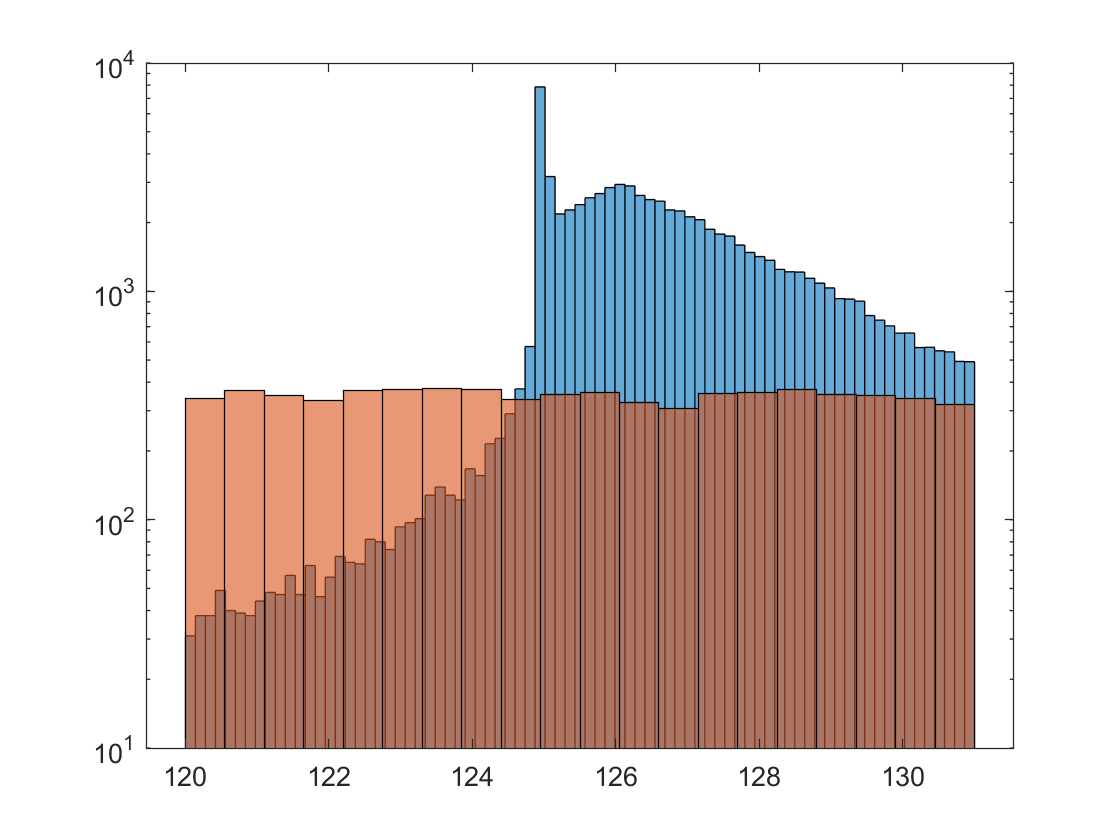

histogram(higgs(4,:),'BinLimits',[120,131]);
hold on
histogram(qcd(4,:),'BinLimits',[120,131]);
set(gca,'Yscale','log')
hold off

<SYSTEMATIC CUTS (loop)>

-- loopify the cuts 

- Try different mass cuts systematically

- Evaluate expeced significance for each set of mass cuts

- Identify the set of the mass cuts which give you the highest significance.

my procedure 

- Make stacked histogram plots for the rest of features

- Set A of plots without any event selection

- Can you identify another feature as discriminative as mass feature (i.e. equal or better significance after feature cut)

- Set B of plots with your optimal mass cuts

- Can you identify additional feature to further imrpove expected signifiance?

- Optimize event selections using multiple features (if necessary)

- Find a set of feature cuts which can help you to achieve the best significance.

- Compare significance (before/after event selection) dervied in your pT samples to your lab partner. Describe your findings.